# RUL

## Generation Prognostic data from model

Generate response data from the model. In further steps this dataset can be imported as data ensemble format.

clc; clear all; close all;
addpath("../models/")
run("params.m");

fault_code = "1100001"

Healthy system behavior 


disp('[INFO] Parameters were loaded');

[INFO] Parameters were loaded


%%
output_path = '../data/data_gen_mdl_air_leak';
model = 'model_equation_simply_valves';

### Air leak from B chamber

In this section air leak fault is simulated. Assuming that air leak discharge coefficient has expotential growing. Simulated data has different number of cycles, that represent different air leak fault dynamic. Simulated data represents run-to-failure data for different stands. Where ID represent identification number of stand.

generate_data = 0;
id_max = 25;
if generate_data
    air_leak = 1;

    for i = 0:1:id_max
        output_path = '../data/data_gen_rul/id_' + string(i) +'/';
        
        load_system(model);
        open_system(model);
        runParallel = 1;
        
        
        % Run using Parallel Computing Toolbox
        if runParallel && isempty(gcp('nocreate'))
            parpool([2,6]);
        end
        
        % Parameters changing in the time. For system behavior simulation purposes.
        C_leak_values = linspace(1e-5, 1e-3, (100+100*rand));
        C_leak_values = C_leak_values.^2 - rand*C_leak_values.^3;
        for k = 1:numel(C_leak_values)
            C_leak_values(k) = C_leak_values(k) + rand*0.1*C_leak_values(k);   
        end
        hold on
        plot(C_leak_values)
        title("Dischrge coefficient air leak")
        xlabel("Cycle")
        ylabel("Discharge coefficient")

        
        for j = 1:numel(C_leak_values)
            tmp = Simulink.SimulationInput(model);
            tmp = setVariable(tmp, 'C_leak', C_leak_values(j));
            tmp = setVariable(tmp, 'cycle', j);
            tmp = setVariable(tmp, 'id', i);
            simin(j) = tmp;
        end
        
        if ~exist(fullfile(pwd, output_path), 'dir')
            mkdir(fullfile(pwd, output_path))
        end
        
        [status,e] = generateSimulationEnsemble(simin, ...
            fullfile(pwd, output_path), 'UseParallel', runParallel);
        if status
            disp("[INFO] Data was successfully generated")
        else
            warning("Fault in data generation")
        end
        clear simin
    end
end

clear all;
addpath("../utils/")
output_path = '../data/data_gen_rul';
ensemble = simulationEnsembleDatastore(output_path);
ensemble.SelectedVariables = ["ID"; "Cycle"];
fix = 0;
if fix
    ensemble = handler_fix_datastore(ensemble);
end

reset(ensemble)
ensemble.SelectedVariables = ["Time"; ... 
                              "Id"; ...
                              "LeverPosition"; ...
                              "LeverVelocity"; ...
                              "FlowContraction"; ...
                              "FlowExtrusion"; ...
                              ];
member = read(ensemble)

member = 1×6 table
    Time    Id       LeverPosition          LeverVelocity         FlowContraction         FlowExtrusion   
    ____    __    ___________________    ___________________    ___________________    ___________________

     1      0     {10001×1 timetable}    {10001×1 timetable}    {10001×1 timetable}    {10001×1 timetable}


reset(ensemble)

## Import calculated features

In this section FlowContraction sensor used.

Import calculated featuretable; best feature from Monotonicity: 

rul_featuretable = load("rul_flow_featuretable.mat").rul_flow_featuretable;
rul_featuretable = sortrows(rul_featuretable, "Time")

rul_featuretable = 3720×15 table
    Time    Id    FlowContraction_stats/ClearanceFactor    FlowContraction_stats/CrestFactor    FlowContraction_stats/ImpulseFactor    FlowContraction_stats/Kurtosis    FlowContraction_stats/Mean    FlowContraction_stats/PeakValue    FlowContraction_stats/RMS    FlowContraction_stats/SINAD    FlowContraction_stats/SNR    FlowContraction_stats/ShapeFactor    FlowContraction_stats/Skewness    FlowContraction_stats/Std    FlowContraction_stats/THD
    ____    __    _____________________________________    _________________________________    ___________________________________    ______________________________

Extract some Id

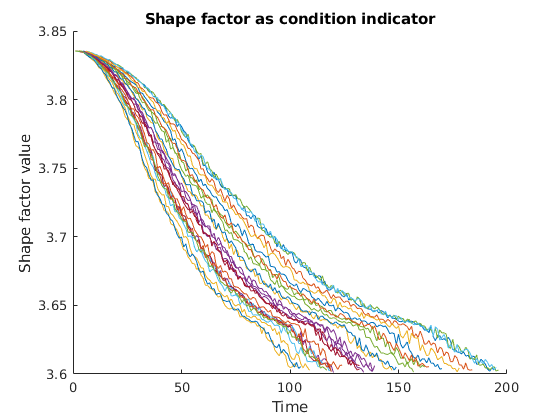

figure
ii = 0:1:25;
for i = ii
    var = rul_featuretable(rul_featuretable.Id == i, :);
    hold on
    plot(var.Time, var.("FlowContraction_stats/ShapeFactor"))
end
hold off
title("Shape factor as condition indicator")
xlabel("Time")
ylabel("Shape factor value")

%rul_featuretable(rul_featuretable.Id == 1, :)
i_train = rul_featuretable.Id == 5:25;
n = size(i_train);
n = n(2);
var = i_train(:,1);
for i = 1:1:(n-1)
    tmp = i_train(:,i) | i_train(:,i+1);
    var =  var | tmp;
end
i_train = var;
i_test = rul_featuretable.Id == 0:5;
n = size(i_test);
n = n(2);
var = i_test(:,1);
for i = 1:1:(n-1)
    tmp = i_test(:,i) | i_test(:,i+1);
    var =  var | tmp;
end
i_test = var;


train_data = rul_featuretable(var, :)

train_data = 888×15 table
    Time    Id    FlowContraction_stats/ClearanceFactor    FlowContraction_stats/CrestFactor    FlowContraction_stats/ImpulseFactor    FlowContraction_stats/Kurtosis    FlowContraction_stats/Mean    FlowContraction_stats/PeakValue    FlowContraction_stats/RMS    FlowContraction_stats/SINAD    FlowContraction_stats/SNR    FlowContraction_stats/ShapeFactor    FlowContraction_stats/Skewness    FlowContraction_stats/Std    FlowContraction_stats/THD
    ____    __    _____________________________________    _________________________________    ___________________________________    ______________________________   

test_data = rul_featuretable(i_test, :)

test_data = 888×15 table
    Time    Id    FlowContraction_stats/ClearanceFactor    FlowContraction_stats/CrestFactor    FlowContraction_stats/ImpulseFactor    FlowContraction_stats/Kurtosis    FlowContraction_stats/Mean    FlowContraction_stats/PeakValue    FlowContraction_stats/RMS    FlowContraction_stats/SINAD    FlowContraction_stats/SNR    FlowContraction_stats/ShapeFactor    FlowContraction_stats/Skewness    FlowContraction_stats/Std    FlowContraction_stats/THD
    ____    __    _____________________________________    _________________________________    ___________________________________    ______________________________    


for i = 1:1:25
    tmp = rul_featuretable(rul_featuretable.Id == i, ["Time", "FlowContraction_stats/ShapeFactor"]);
    train_arr{i} = table(tmp.Time, tmp.("FlowContraction_stats/ShapeFactor"), 'VariableNames', ["Time", "Condition"]);
end

train_arr = train_arr'

train_arr = 25×1 cell array
    {184×2 table}
    {109×2 table}
    {120×2 table}
    {162×2 table}
    {119×2 table}
    {119×2 table}
    {170×2 table}
    {119×2 table}
    {103×2 table}
    {139×2 table}
    {196×2 table}
    {195×2 table}
    {132×2 table}
    {105×2 table}
    {124×2 table}
    {147×2 table}


test_data = rul_featuretable(rul_featuretable.Id == 0, "FlowContraction_stats/ShapeFactor").("FlowContraction_stats/ShapeFactor")

test_data =     3.8355
    3.8353
    3.8351
    3.8352
    3.8348
    3.8344
    3.8348
    3.8343
    3.8340
    3.8332


test_data = test_data(1:end-70)

test_data =     3.8355
    3.8353
    3.8351
    3.8352
    3.8348
    3.8344
    3.8348
    3.8343
    3.8340
    3.8332


mdl = residualSimilarityModel('Method',"arma3",'LifeTimeUnit',"cycles");
fit(mdl, train_arr, "Time", "Condition")

estRUL = predictRUL(mdl, test_data)

estRUL = 13.3678

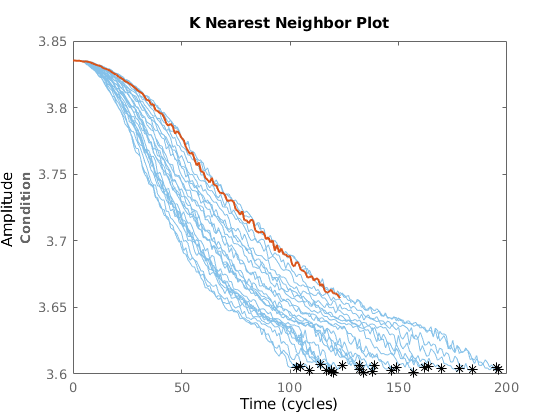

figure
compare(mdl, test_data)

## Survival Covariative Model

train_data = rul_featuretable(:,["Time", "Id", "LeverPosition_stats/Skewness", "FlowExtrusion_stats/Mean"])

train_data = 770×4 table
    Time    Id    LeverPosition_stats/Skewness    FlowExtrusion_stats/Mean
    ____    __    ____________________________    ________________________

     1       0              0.16557                        2.7442         
     1      10              0.16556                        2.7442         
     1       1              0.16555                        2.7442         
     1       2              0.16556                        2.7442         
     1       3              0.16555                        2.7442         
     1       4              0.16556                        2.7442         
     1       5              0.16556                        2.7442         
     1       6              0.16556                        2.7442         
     1       7              0.16557                        2.7442         
     1       

train_data = table(train_data.Time, train_data.Id, train_data.("LeverPosition_stats/Skewness"), train_data.("FlowExtrusion_stats/Mean"), 'VariableNames', {'Time', 'Id', 'Position', 'Flow'})

train_data = 770×4 table
    Time    Id    Position     Flow 
    ____    __    ________    ______

     1       0    0.16557     2.7442
     1      10    0.16556     2.7442
     1       1    0.16555     2.7442
     1       2    0.16556     2.7442
     1       3    0.16555     2.7442
     1       4    0.16556     2.7442
     1       5    0.16556     2.7442
     1       6    0.16556     2.7442
     1       7    0.16557     2.7442
     1       8    0.16556     2.7442
     1       9    0.16556     2.7442
     2       0    0.16556     2.7442
     2      10    0.16554     2.7442
     2       1    0.16553     2.7442
     2       2    0.16555     2.7442
     2       3    0.16554     2.7442


mdl = covariateSurvivalModel('LifeTimeVariable',"Time",'LifeTimeUnit',"cycles",...
   'DataVariables',["Position","Flow", "Id"],'EncodedVariables',"Id");

fit(mdl,train_data)

Iterations terminated because relative function value changing by less than OPTIONS.TolFun


test_data = table(62, 0, 0.11, 2.74, 'VariableNames', {'Time','Id', 'Position', 'Flow'})

test_data = 1×4 table
    Time    Id    Position    Flow
    ____    __    ________    ____

     62     0       0.11      2.74


est_rul = predictRUL(mdl, test_data)

est_rul = 5.6976

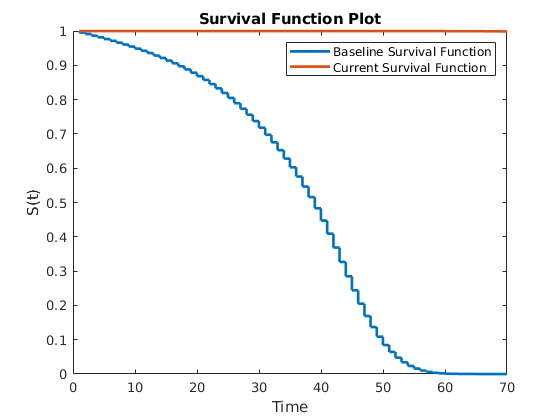

plot(mdl, test_data)

## Functions

function [dataTrain, dataTest] = split_dataset(data)
    cv = cvpartition(size(data,1), 'HoldOut', 0.3);
    idx = cv.test;      
    dataTrain = data(~idx, :);
    dataTest = data(idx, :);
end

function [accuracy] = confusion_matrix_plot_handler(mdl, features)
    required_features = mdl.RequiredVariables;
    targetLabels = features(:,"Label");
    inputTable = features(:, required_features);
    predictedLabels = mdl.predictFcn(inputTable);
    [C,order] = confusionmat(table2array(targetLabels),predictedLabels);
    accuracy = sum(table2array(targetLabels) == predictedLabels)/numel(predictedLabels);
    fprintf("Accuracy is %0.2f %% \n", accuracy*100)
    figure
    confusionchart(C, order)
end

function ensemble = handler_fix_datastore(ensemble)
% Append data
ensemble.DataVariables = [ensemble.DataVariables; "Time"; "Id"];

reset(ensemble);
while hasdata(ensemble)
    data = read(ensemble);
    cycle = data.Cycle{1,1}.Data;
    id = data.ID{1,1}.Data;
    writeToLastMemberRead(ensemble, "Time", cycle);
    writeToLastMemberRead(ensemble, "Id", id);
end
end

function ensemble = fix_label(ensemble)
reset(ensemble);
while hasdata(ensemble)
    data = read(ensemble);
    lab = data.Label{1,1};
    writeToLastMemberRead(ensemble, "Label", lab);
end
end


function signal = sim_signal_extract(signal)
    name = signal.Name;
    signal = ts2timetable(signal).(string(name))(1:end-1);
end

function [] = save_data(path, data, i)
    filename = path + "data_" + string(i) + ".mat";
    save(filename, "data")
end

function [label, r_pos_tt, r_vel_tt, r_fe_tt, r_fc_tt] = generate_residuals(reference, member, t)
    Ts = 1e-3;
    label = string(member.Label{1,1});
    position = member.LeverPosition{1,1};
    velocity = position; velocity.Data = [diff(position.Data)/Ts; 0];
    flow_ex = member.FlowExtrusion{1,1};
    flow_con = member.FlowContraction{1,1};
    
    r_pos = reference.position-position.Data;
    r_vel = reference.velocity-velocity.Data;
    r_fe = reference.flow_ex-flow_ex.Data;
    r_fc = reference.flow_con-flow_con.Data;
    
    r_pos_tt = timetable(r_pos, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
    r_vel_tt = timetable(r_vel, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
    r_fe_tt = timetable(r_fe, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
    r_fc_tt = timetable(r_fc, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
end
